**Name: Anish Gorantiwar**

**Applied Linear Systems - Midterm Project**

**Problem 1:** Derive a complete state-space model for the AUV, including a state equation and an output equation.

We have been given three linearized external forces and moments equations which has the outputs in the body coordinate frame. 

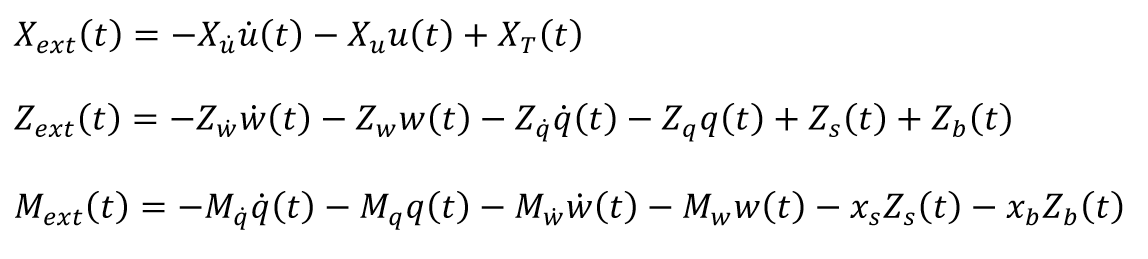

All the external forces and the moments have been written in term of mass of the AUV (m), mass moment of inertia (I) and the model outputs.


$$X_{\mathrm{ext}} \left(t\right)=m\dot{u} \left(t\right)$$



$$Z_{\mathrm{ext}} \left(t\right)=m\dot{w} \left(t\right)$$



$$M_{\mathrm{ext}} \left(t\right)=I_y \dot{q} \left(t\right)$$


The three force and moment equations have first been transformed to the world coordinate frame using the follwing set of mapping equations:


$$\begin{array}{l}\dot{x} \left(t\right)=u\left(t\right)\\\dot{z} \left(t\right)=w\left(t\right)\\\dot{\theta} 
\left(t\right)=q\left(t\right)\end{array}$$


The resulting set of three second order differential equations are as follows:


$$\begin{array}{l}m\ddot{x} =-X_{\dot{u} } \ddot{x} -X_u \dot{x} +X_T \\m\ddot{z}  =-Z_{\dot{w} } \ddot{z} -Z_w \dot{z} -Z_{\dot{q} } \theta^¨ -Z_q \dot{\theta} +Z_s  +Z_b \\I_y \ddot{z} =-M_{\dot{q} } \theta^¨ -M_q \dot{\theta} -M_{\dot{w} } \ddot{z}  -M_w \dot{z} -x_s Z_s -x_b Z_b \end{array}$$


In the above equations, all the parameters are split into the follwoing groups:

**Inputs:** $X_T ,Z_s ,Z_b$

**Outputs (in world coordinate frame):** $\theta ,x,z$ 

From the equations given, the following states have been decided:


$$\begin{array}{l}x_1 =x\\x_2 =\dot{x} \\x_3 =z\\x_4 =\dot{z} \\x_5 =\theta 
\\x_6 =\dot{\theta} \end{array}$$


The resulting six first order differential equations are as follows:


$$\begin{array}{l}{\dot{x} }_1 =x_2 \;\\{\dot{x} }_2 =\frac{1}{m+X_{\dot{u}  } }\left\lbrack -X_u x_2 +X_T \right\rbrack \\{\dot{x} }_3 =x_4 \\{\dot{x} }_4  =\frac{1}{1-\left\lbrack \frac{Z_{\dot{q} } M_{\dot{w} } }{\left(I_y +M_{\dot{q}  } \right)\left(m+Z_{\dot{w} } \right)}\right\rbrack }\left\lbrace \left.\frac{1}{m+Z_{\dot{w}  } }\left\lbrack -Z_w x_4 -Z_{\dot{q} } \left\lbrack \frac{1}{I_y +M_{\dot{q}  } }\left(-M_q x_6 -M_w x_4 -x_s Z_s -x_b z_b \right)\right\rbrack \right\rbrack  -Z_q x_6 +Z_s +Z_b \right\rbrack \right\rbrace \\{\dot{x} }_5 =x_6 \\{\dot{x}  }_6 =\frac{1}{1-\left\lbrack \frac{Z_{\dot{q} } M_{\dot{w} } }{\left(I_y +M_{\dot{q}  } \right)\left(m+Z_{\dot{w} } \right)}\right\rbrack }\left\lbrace \left.\frac{1}{I_y  +M_{\dot{q} } }\left\lbrack -M_q x_6 -M_{\dot{w} } \left\lbrack \frac{1}{m+Z_{\dot{w}  } }\left(-Z_w x_4 -Z_q x_6 +Z_s +Z_b \right)\right\rbrack \right\rbrack -M_w  x_4 +Z_s x_s +Z_b x_b \right\rbrack \right\rbrace \end{array}$$


The above set of 6 equations can be written in proper state space form as follows:


$$\begin{array}{l}{\dot{x} }_1 =0x_1 +x_2 +0x_3 +0x_4 +0x_5 +0x_6 \\{\dot{x} 
}_2 =0x_1 +\left(\frac{-X_u }{m+X_{\dot{u} } }\right)x_2 +0x_3 +0x_4 +0x_5 +0x_6 
+\frac{X_T }{\left(m+X_{\dot{u} } \right)}\\{\dot{x} }_3 =0x_1 +{0x}_2 +0x_3 
+x_4 +0x_5 +0x_6 \\{\dot{x} }_4 =0x_1 +0x_2 +0x_3 +\left(\frac{Z_{\dot{q} } 
M_w -Z_w \left(I_y +M_{\dot{q} } \right)}{\left(I_y +M_{\dot{q} } \right)\left(m+Z_{\dot{w} 
} \right)-Z_{\dot{q} } M_{\dot{w} } \;}\right)x_4 +0x_5 +\left(\frac{Z_{\dot{q} 
} M_q -Z_q \left(I_y +M_{\dot{q} } \right)}{\left(I_y +M_{\dot{q} } \right)\left(m+Z_{\dot{w} 
} \right)-Z_{\dot{q} } M_{\dot{w} } \;}\right)x_6 +\frac{Z_{\dot{q} } \left(x_s 
Z_s +x_b Z_b \right)}{\left(I_y +M_{\dot{q} } \right)\left(m+Z_{\dot{w} } \right)-Z_{\dot{q} 
} M_{\dot{w} } }+\frac{\left(I_y +M_{\dot{q} } \right)\left(Z_s +Z_b \right)}{\left(I_y 
+M_{\dot{q} } \right)\left(m+Z_{\dot{w} } \right)-Z_{\dot{q} } M_{\dot{w} } 
}\\{\dot{x} }_5 =0x_1 +{0x}_2 +0x_3 +0x_4 +0x_5 +x_6 \\{\dot{x} }_6 =0x_1 +{0x}_2 
+0x_3 +\left(\frac{M_{\dot{w} } Z_w -M_w \left(m+Z_{\dot{w} } \right)}{\left(I_y 
+M_{\dot{q} } \right)\left(m+Z_{\dot{w} } \right)-Z_{\dot{q} } M_{\dot{w} } 
}\right)x_4 +0x_5 +\left(\frac{M_{\dot{w} } Z_q -M_q \left(m+Z_{\dot{w} } \right)}{\left(I_y 
+M_{\dot{q} } \right)\left(m+Z_{\dot{w} } \right)-Z_{\dot{q} } M_{\dot{w} } 
}\right)x_6 +\frac{M_{\dot{w} } \left(Z_s +Z_b \right)}{\left(I_y +M_{\dot{q} 
} \right)\left(m+Z_{\dot{w} } \right)-Z_{\dot{q} } M_{\dot{w} } }+\frac{\left(m+Z_{\dot{w} 
} \right)\left(x_s Z_s +x_b Z_b \right)}{\left(I_y +M_{\dot{q} } \right)\left(m+Z_{\dot{w} 
} \right)-Z_{\dot{q} } M_{\dot{w} } }\end{array}$$


In state space form, the equations can be written as follows:


$$\left\lbrack \begin{array}{c}{\dot{x} }_1 \\{\dot{x} }_2 \\{\dot{x} }_3 
\\{\dot{x} }_4 \\{\dot{x} }_5 \\{\dot{x} }_6 \end{array}\right\rbrack =\left\lbrack 
\begin{array}{cccccc}0 & 1 & 0 & 0 & 0 & 0\\0 & \frac{-X_u }{m+X_{\dot{u} } 
} & 0 & 0 & 0 & 0\\0 & 0 & 0 & 1 & 0 & 0\\0 & 0 & 0 & \left(\frac{Z_{\dot{q} 
} M_w -Z_w \left(I_y +M_{\dot{q} } \right)}{\left(I_y +M_{\dot{q} } \right)\left(m+Z_{\dot{w} 
} \right)-Z_{\dot{q} } M_{\dot{w} } \;}\right) & 0 & \left(\frac{Z_{\dot{q} 
} M_q -Z_q \left(I_y +M_{\dot{q} } \right)}{\left(I_y +M_{\dot{q} } \right)\left(m+Z_{\dot{w} 
} \right)-Z_{\dot{q} } M_{\dot{w} } \;}\right)\\0 & 0 & 0 & 0 & 0 & 1\\0 & 0 
& 0 & \left(\frac{M_{\dot{w} } Z_w -M_w \left(m+Z_{\dot{w} } \right)}{\left(I_y 
+M_{\dot{q} } \right)\left(m+Z_{\dot{w} } \right)-Z_{\dot{q} } M_{\dot{w} } 
}\right) & 0 & \left(\frac{M_{\dot{w} } Z_q -M_q \left(m+Z_{\dot{w} } \right)}{\left(I_y 
+M_{\dot{q} } \right)\left(m+Z_{\dot{w} } \right)-Z_{\dot{q} } M_{\dot{w} } 
}\right)\end{array}\right\rbrack \left\lbrack \begin{array}{c}x_1 \\x_2 \\x_3 
\\x_4 \\x_5 \\x_6 \end{array}\right\rbrack +\left\lbrack \begin{array}{ccc}0 
& 0 & 0\\\frac{1}{\left(m+X_{\dot{u} } \right)} & 0 & 0\\0 & 0 & 0\\0 & \frac{\left(Z_{\dot{q} 
} x_s +I_y +M_{\dot{q} } \right)}{\left(I_y +M_{\dot{q} } \right)\left(m+Z_{\dot{w} 
} \right)-Z_{\dot{q} } M_{\dot{w} } } & \frac{\left(Z_{\dot{q} } x_b +I_y +M_{\dot{q} 
} \right)}{\left(I_y +M_{\dot{q} } \right)\left(m+Z_{\dot{w} } \right)-Z_{\dot{q} 
} M_{\dot{w} } }\\0 & 0 & 0\\0 & \frac{\left(M_{\dot{w} } +mx_s +Z_{\dot{w} 
} x_s \right)}{\left(I_y +M_{\dot{q} } \right)\left(m+Z_{\dot{w} } \right)-Z_{\dot{q} 
} M_{\dot{w} } } & \frac{\left(M_{\dot{w} } +mx_b +Z_{\dot{w} } x_b \right)}{\left(I_y 
+M_{\dot{q} } \right)\left(m+Z_{\dot{w} } \right)-Z_{\dot{q} } M_{\dot{w} } 
}\end{array}\right\rbrack \left\lbrack \begin{array}{c}X_T \\Z_s \\Z_b \end{array}\right\rbrack$$



$$\left\lbrack \begin{array}{c}\theta \\Z\\x\end{array}\right\rbrack =\left\lbrack 
\begin{array}{cccccc}0 & 0 & 0 & 0 & 1 & 0\\0 & 0 & 1 & 0 & 0 & 0\\1 & 0 & 0 
& 0 & 0 & 0\end{array}\right\rbrack \left\lbrack \begin{array}{c}x_1 \\x_2 \\x_3 
\\x_4 \\x_5 \\x_6 \end{array}\right\rbrack +\left\lbrack \begin{array}{ccc}0 
& 0 & 0\\0 & 0 & 0\\0 & 0 & 0\end{array}\right\rbrack \left\lbrack \begin{array}{c}X_T 
\\Z_s \\Z_b \end{array}\right\rbrack$$


The state, input, output and the direct transmission matrices can be evaluated as follows using the MATLAB 'syms' function:

clc
clear 
close all

syms X_u m X_u_dot X_t Z_q_dot M_w Z_w I_y M_q_dot Z_w_dot M_w_dot x_s Z_s x_b Z_b M_q Z_q
D = [0,0,0;0,0,0;0,0,0]

D =      0     0     0
     0     0     0
     0     0     0


C = [1,0,0,0,0,0;0,0,1,0,0,0;0,0,0,0,1,0]

C =      1     0     0     0     0     0
     0     0     1     0     0     0
     0     0     0     0     1     0


B = [0,0,0;(1/(m+X_u_dot)),0,0;0,0,0;0,(((Z_q_dot*x_s)+(I_y)+(M_q_dot))/((I_y+M_q_dot)*(m+Z_w_dot)-(Z_q_dot*M_w_dot))),...
    (((Z_q_dot*x_b)+(I_y)+(M_q_dot))/((I_y+M_q_dot)*(m+Z_w_dot)-(Z_q_dot*M_w_dot)));0,0,0;0,...
    -(((M_w_dot)+(m*x_s)+(Z_w_dot*x_s))/((I_y+M_q_dot)*(m+Z_w_dot)-(Z_q_dot*M_w_dot))),...
    -(((M_w_dot)+(m*x_b)+(Z_w_dot*x_b))/((I_y+M_q_dot)*(m+Z_w_dot)-(Z_q_dot*M_w_dot)))]

$$B = \begin{array}{l} \left(\begin{array}{ccc} 0 & 0 & 0\\ \frac{1}{X_{\dot{u}}+m} & 0 & 0\\ 0 & 0 & 0\\ 0 & -\frac{I_{y}+M_{\dot{q}}+Z_{\dot{q}}\,x_{s}}{\sigma_{1}} & -\frac{I_{y}+M_{\dot{q}}+Z_{\dot{q}}\,x_{b}}{\sigma_{1}}\\ 0 & 0 & 0\\ 0 & \frac{M_{\dot{w}}+Z_{\dot{w}}\,x_{s}+m\,x_{s}}{\sigma_{1}} & \frac{M_{\dot{w}}+Z_{\dot{w}}\,x_{b}+m\,x_{b}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=M_{\dot{w}}\,Z_{\dot{q}}-\left(Z_{\dot{w}}+m\right)\,\left(I_{y}+M_{\dot{q}}\right) \end{array}$$

A = [0,1,0,0,0,0;0, -(X_u/(m+X_u_dot)),0,0,0,0; 0,0,0,1,0,0;0,0,0, (((Z_q_dot*M_w)-(Z_w)*(I_y+M_q_dot))/((I_y+M_q_dot)*(m+Z_w_dot)-(Z_q_dot*M_w_dot))),...
    0,(((Z_q_dot*M_q)-(Z_q)*(I_y+M_q_dot))/((I_y+M_q_dot)*(m+Z_w_dot)-(Z_q_dot*M_w_dot)));0,0,0,0,0,1;0,0,0,...
    (((M_w_dot*Z_w)-(M_w)*(m+Z_w_dot))/((I_y+M_q_dot)*(m+Z_w_dot)-(Z_q_dot*M_w_dot))),0,...
    (((M_w_dot*Z_q)-(M_q)*(m+Z_w_dot))/((I_y+M_q_dot)*(m+Z_w_dot)-(Z_q_dot*M_w_dot)))]

$$A = \begin{array}{l} \left(\begin{array}{cccccc} 0 & 1 & 0 & 0 & 0 & 0\\ 0 & -\frac{X_{u}}{X_{\dot{u}}+m} & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & -\frac{M_{w}\,Z_{\dot{q}}-Z_{w}\,\left(I_{y}+M_{\dot{q}}\right)}{\sigma_{1}} & 0 & -\frac{M_{q}\,Z_{\dot{q}}-Z_{q}\,\left(I_{y}+M_{\dot{q}}\right)}{\sigma_{1}}\\ 0 & 0 & 0 & 0 & 0 & 1\\ 0 & 0 & 0 & -\frac{M_{\dot{w}}\,Z_{w}-M_{w}\,\left(Z_{\dot{w}}+m\right)}{\sigma_{1}} & 0 & -\frac{M_{\dot{w}}\,Z_{q}-M_{q}\,\left(Z_{\dot{w}}+m\right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=M_{\dot{w}}\,Z_{\dot{q}}-\left(Z_{\dot{w}}+m\right)\,\left(I_{y}+M_{\dot{q}}\right) \end{array}$$

**Problem 2:** Using the numerical values and formulas listed below, compute the following parameters at the top of your Matlab script. (All parameters have SI units).

m1 = 500;
L1 = 25;
I_y1 = (1/300)*m1*(L1^2);
X_u_dot1 = (1/30)*m1;
X_u1 = 94;
Z_w_dot1 = (1/10)*m1;
Z_w1 = 470;
Z_q_dot1 = (1/20)*m1;
Z_q1 = 950;
M_q_dot1 = (1/20)*I_y1;
M_q1 = 1100;
M_w_dot1 = (1/40)*I_y1;
M_w1 = 320;
x_s1 = -(1/3)*L1;
x_b1 = (1/3)*L1;
U_max1 = 3000000;

B = subs(B,[m, X_u_dot, Z_q_dot,I_y, M_q_dot, Z_w_dot, M_w_dot,x_s,x_b],[m1, X_u_dot1, Z_q_dot1,I_y1, M_q_dot1, Z_w_dot1, M_w_dot1, x_s1,x_b1]);
B = double(B)

B =          0         0         0
    0.0019         0         0
         0         0         0
         0    0.0015    0.0022
         0         0         0
         0    0.0076   -0.0077


A = subs(A,[X_u, m, X_u_dot, Z_q_dot, M_w, Z_w, I_y, M_q_dot, Z_w_dot, M_w_dot, M_q, Z_q],[X_u1, m1, X_u_dot1, Z_q_dot1,...
    M_w1, Z_w1, I_y1, M_q_dot1, Z_w_dot1, M_w_dot1, M_q1, Z_q1]);
A = double(A)

A =          0    1.0000         0         0         0         0
         0   -0.1819         0         0         0         0
         0         0         0    1.0000         0         0
         0         0         0   -0.8422         0   -1.6834
         0         0         0         0         0    1.0000
         0         0         0   -0.2725         0   -0.9656


**Problem 3:** Use the variables defined in Problem 2 to construct the A, B, C, and D matrices for your linear state-space model, then use these matrices to generate an LTI object called ol_sys.

The state space equations are given by:


$$\begin{array}{l}\dot{x} =\mathrm{Ax}+\mathrm{Bu}\\y=\mathrm{Cx}+\mathrm{Du}\end{array}$$


where A, B, C, D are the state, input, output and the direct transmission matrices respectively. These matrices are obtained by using the six equations as given previously.

ol_sys = ss(A,B,C,D,'StateName',{'Surge Displacement' 'Surge Velocity' 'Heave Displacement' 'Heave Velocity' 'Pitch Angle' 'Pitch Rate' },...
                    'InputName',{'Thrust' 'Stern Thrust' 'Bow Thrust'}, 'OutputName',{'Surge Displacement' 'Heave Displacement' 'Pitch'})

ol_sys =
 
  A = 
                 Surge Displa  Surge Veloci  Heave Displa  Heave Veloci   Pitch Angle
   Surge Displa             0             1             0             0             0
   Surge Veloci             0       -0.1819             0             0             0
   Heave Displa             0             0             0             1             0
   Heave Veloci             0             0             0       -0.8422             0
   Pitch Angle              0             0             0             0             0
   Pitch Rate               0             0             0       -0.2725             0
 
                   Pitch Rate
   Surge Displa             0
   Surge Veloci             0
   Heave Displa             0
   Heave Veloci        -1.683
   Pitch Angle              1
   Pitch Rate         -0.9656
 
  B = 
                       Thrust  Stern Thrust    Bow Thrust
   Surge Displa             0             0             0
   Surge Veloci      0.001935             0

**Problem 4:** Apply the MINREAL function in Matlab to your LTI object from Problem 3 to determine whether your state-space model is a minimum realization. Explain your results

sysr = minreal(ol_sys)

sysr =
 
  A = 
                 Surge Displa  Surge Veloci  Heave Displa  Heave Veloci   Pitch Angle
   Surge Displa             0             1             0             0             0
   Surge Veloci             0       -0.1819             0             0             0
   Heave Displa             0             0             0             1             0
   Heave Veloci             0             0             0       -0.8422             0
   Pitch Angle              0             0             0             0             0
   Pitch Rate               0             0             0       -0.2725             0
 
                   Pitch Rate
   Surge Displa             0
   Surge Veloci             0
   Heave Displa             0
   Heave Veloci        -1.683
   Pitch Angle              1
   Pitch Rate         -0.9656
 
  B = 
                       Thrust  Stern Thrust    Bow Thrust
   Surge Displa             0             0             0
   Surge Veloci      0.001935             0  

After applying the MINREAL function, it can be seen that the input, state and the output matrices remain the same i.e. there are no uncontrollable or unobservable state in state-space models. Hence the system is at minimum realization.

**Problem 5:** Show that the open-loop system is Completely Controllable using all of the control inputs. Determine (and clearly document) whether any subsets of control inputs results in a Completely Controllable system. Justify your results

Co = ctrb(ol_sys);
unco = length(A) - rank(Co)

unco = 0

The uncontrollable state indicates that Co has Full Rank 2. Therefore, the system is completely controllable.

Now we have to determine whether any subsets of the control inputs result in a Completely Controllable System. This is taken into account by considering the following three subsets: $\left\lbrack X_{T,} \;Z_s \right\rbrack ,\left\lbrack X_{T,} \;Z_b \right\rbrack \;\textrm{and}\;\left\lbrack Z_{b,} \;Z_s \right\rbrack \ldotp \;$

Co_1 = ctrb(A,B(1:6,1:2));
unco_1 = length(A) - rank(Co_1)

unco_1 = 1

Co_2 = ctrb(A,B(1:6,2:3));
unco_2 = length(A) - rank(Co_2)

unco_2 = 2

Co_3 = ctrb(A,B(:,[1,end]));
unco_3 = length(A) - rank(Co_3)

unco_3 = 1

It can be seen that the system is not controllable for any of the three subsets as the uncontrollable state indicate that Co_1, Co_2 and Co_3 do not have a full rank. Hence it is not completely controllable i.e. the system cannot be completely controlled by having a control of over only two out of the three inputs.

**Problem 6:** Compute the open loop poles, the natural frequencies with units of Hz, and the damping ratios for each eigenvalue. Tabulate and display your results using the Matlab TABLE function

The open loop poles i.e. the eigen values of the matrix are determined as follows:

[V,D_1] = eig(A);

Therefore, the system has 6 poles out of which three poles lie at the origin and the remaining three in the left hand side of the complex plane. This indicates that the system is Marginally Stable.

The natural freqeuncies and the damping ratio for the system are given as follows:

[wn,zeta] = damp(ol_sys)

wn =          0
         0
         0
    0.1819
    0.2238
    1.5840


zeta =     -1
    -1
    -1
     1
     1
     1


The open loop poles, natural freqeuncies and the damping ratios are tabulated as follows:

Open_Loop_Poles = diag(D_1);
Natural_Frequencies_Hz = wn*(1/(2*pi));
Damping_Ratios = zeta;
T = table(Open_Loop_Poles,Natural_Frequencies_Hz,Damping_Ratios)

T = 6×3 table
    Open_Loop_Poles    Natural_Frequencies_Hz    Damping_Ratios
    _______________    ______________________    ______________

              0                      0                 -1      
              0                      0                 -1      
         -1.584                      0                 -1      
       -0.22377               0.028956                  1      
              0               0.035615                  1      
       -0.18194                 0.2521                  1      


**Problem 7:**

The initial values given in the problem are:


$$\begin{array}{l}x\left(0\right)=50\\z\left(0\right)=350\\\theta \left(0\right)={45}^0 
\\u\left(0\right)=100\\w\left(0\right)=-300\\q\left(0\right)=0\end{array}$$


The initial condition vector is given by as follows:

x_0 = 50;
z_0 = 350;
theta_0 = 45*(pi/180);
u_0 = 100;
w_0 = -300;
q_0 = 0;
Initial_Condition_Vector = [x_0 u_0 z_0 w_0 theta_0 q_0]

Initial_Condition_Vector =    50.0000  100.0000  350.0000 -300.0000    0.7854         0


The response of the system for the specified initial conditions can be obtained as follows:

[y,t,x] = initial(ol_sys,Initial_Condition_Vector);
STS = lsiminfo(y,t,'SettlingTimeThreshold',0.05);
Settling_Times_S = extractfield(STS,'SettlingTime')

Settling_Times_S =    16.3958   12.8804   14.0556


The open loop response outputs with a marker on 5% settling time are given as follows:

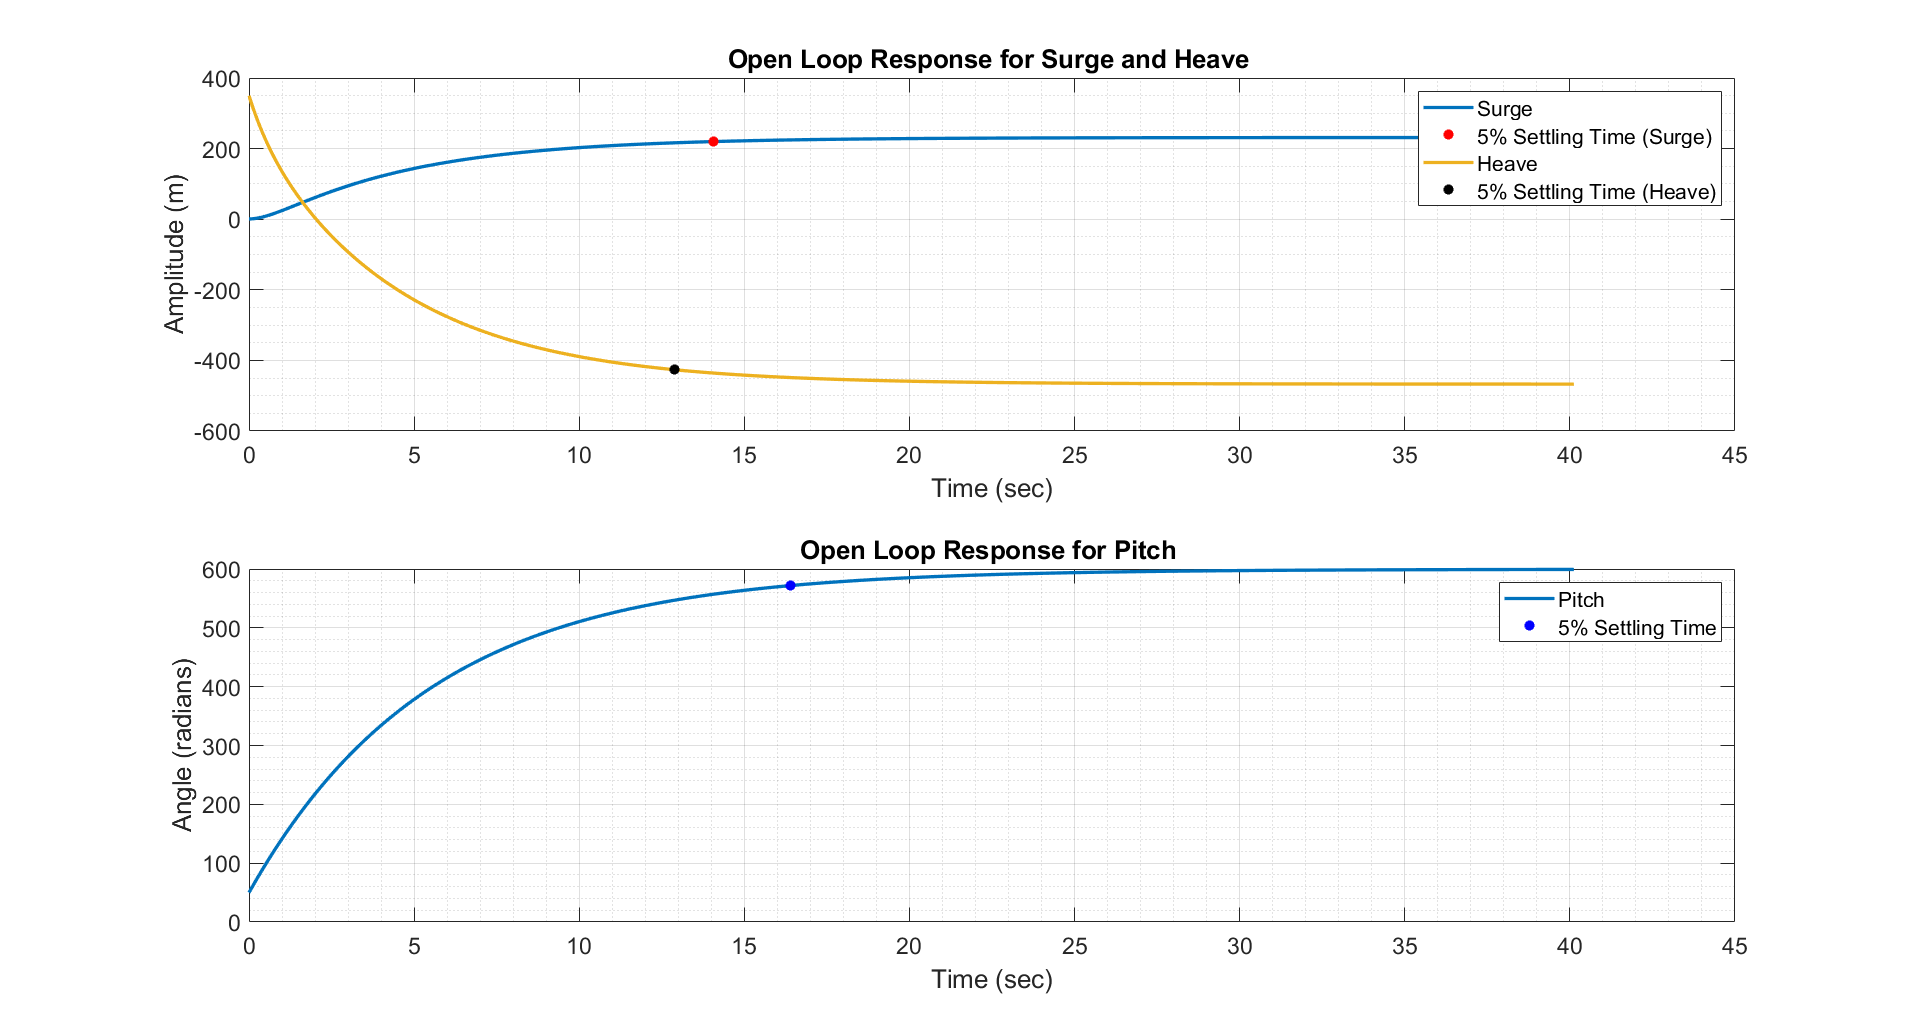

Settling_Time_1 = Settling_Times_S(1,1);
Settling_Time_2 = Settling_Times_S(1,2);
Settling_Time_3 = Settling_Times_S(1,3);

vq1 = interp1(t,y(:,3),Settling_Time_3);
vq2 = interp1(t,y(:,2),Settling_Time_2);
vq3 = interp1(t,y(:,1),Settling_Time_1);

figure (1)
subplot(2,1,1);
plot(t,y(:,3),Settling_Time_3,vq1,'r*','LineWidth',2);
hold on
plot(t,y(:,2),Settling_Time_2,vq2,'k*','LineWidth',2);
xlabel('Time (sec)')
ylabel('Amplitude (m)')
legend('Surge', '5% Settling Time (Surge)','Heave','5% Settling Time (Heave)')
title('Open Loop Response for Surge and Heave ');
set(gcf, 'Units','Normalized','OuterPosition',[0,0.04,1,0.96]);
grid on
hold off
set(gca,'FontSize',14)
grid minor

subplot(2,1,2);
plot(t,y(:,1),Settling_Time_1,vq3,'b*','LineWidth',2);
legend('Pitch','5% Settling Time')
xlabel('Time (sec)')
ylabel('Angle (radians)')
title('Open Loop Response for Pitch ');
set(gcf, 'Units','Normalized','OuterPosition',[0,0.04,1,0.96]);
grid on
set(gca,'FontSize',14)
grid minor

**Problem 8:** Design a full-state feedback controller

The system had three open loop poles at the origin indicating rigid body modes and the other three open loop poles on the left hand side of the complex plane on the real axis. Now the closed loop poles have to be determined such that the criteria of the control input, settling time and submarine passing the tunnel can be met. The closed loop poles selection criteria was determined based on the following factors:

- Initially the poles will be placed on the real axis i.e. no complex poles and all of them on the left hand side of the plane.

- These poles will be varied along the real axis to decide the two bounding limits i.e. poles on the extreme left hand side of the complex plane will increase the control effort whereas bringing them near the imaginary axis will decrease the control effort but increase the settling time.

- Once these limits are decided, then the complex poles can be tried to see the effect of changing damping ratio ($\left.\xi \right)$and the natural frequency ($\left.\omega_n \right)\ldotp$

Initially the following set of poles was decided p=[-1,-2,-3,-5,-3,-4]. The following MATLAB code shows the simulation process for a single set of poles. The overall summary of 5 different set of poles has been provided in the TABLE in the last section.

p = [-3,-3,-6,-7,-6.5,-2];

The Closed-Loop State Matrix is given by

$\left\lbrack A-\mathrm{BG}\right\rbrack \;\mathrm{where}\;G\;\mathrm{is}\;\mathrm{the}\;\mathrm{matrix}\;\mathrm{of}\;\mathrm{Full}\;\mathrm{State}\;\mathrm{Feedback}\;\mathrm{Gains}$. 'G' matrix is calculated by using the 'place' function of MATLAB 

G = place(A,B,p)

G = 	1.0e+03 *

    7.0661    4.4630    0.6612    0.1872    0.0000    0.0000
    0.2231    0.0694    5.5415    2.4229    1.4063    0.1621
    0.2205    0.0687    5.4789    2.4311   -0.9562   -0.8871


CL_SM = [A-(B*G)]

CL_SM =          0    1.0000         0         0         0         0
  -13.6763   -8.8201   -1.2798   -0.3624   -0.0000   -0.0000
         0         0         0    1.0000         0         0
   -0.8066   -0.2511  -20.0370   -9.6799   -0.0000   -0.0000
         0         0         0         0         0    1.0000
   -0.0000   -0.0000   -0.0000   -0.0000  -18.0000   -9.0000


Now, in order to take into account the translation of the coordinate frame from the given origin (Top Left hand corner) to the tunnel position, the initial condition vector has to be changed with respect to the modified coordinate frame. This has been done in 'Initial_Condition_Vector_1'.

Initial_Condition_Vector_1 = [-415, 100, 200, -300, 45*(pi/180),0]

Initial_Condition_Vector_1 =  -415.0000  100.0000  200.0000 -300.0000    0.7854         0


A new system 'ol_sys_1' has been developed in which the State Matrix 'A' is replaced by the Closed Loop State Matrix [A-BG].

ol_sys_1 = ss(CL_SM,B,C,D);

This new system is simulated using the modified initial conditions vector as shown below:

[y_2, t_2, x_2] = initial(ol_sys_1,Initial_Condition_Vector_1);

Now, the original output vector obtained from 'initial' function in MATLAB - 'y_2' is modified to 'y_2_new' in order to take into account the change in coordinate frame. The settling time is calculated by using the 'lsiminfo' function as shown:

y_2_new(:,3) = y_2(:,3)+465;
y_2_new(:,2) = y_2(:,2)+150;
y_2_new(:,1) = y_2(:,1);
ST = lsiminfo(y_2_new,t_2,'SettlingTimeThreshold',0.05);
New_Settling_Times = extractfield(ST,'SettlingTime')

New_Settling_Times =     1.6250    1.1958    1.2233


With the help of the Full State Feedback gain matrix 'G' and the state vector 'x' obtained from the 'initial' command, the control input can be calculated as follows:


$$u\left(t\right)=-\textrm{Gx}\left(t\right)\;$$


The transpose of the state vector has been taken for matrix multiplication.

u_t = -G*x_2';

Maximum value of the control inputs amongst - Xt, Zs and Zb can be obtained by using the 'max' function of MATLAb. This maximum value should be less than 3e6 which has been specified in the problem statement. 

u_max = max(abs(u_t(:)))

u_max = 2.4100e+06

The changes which have been made in the Initial Condition Vector are taken into account by using the modified y vector 'y_2_new':

%animate_auv(t_2,y_2_new(:,3),y_2_new(:,2),y_2_new(:,1));

**Documentation of the five design iterations:**

After following the design process as shown above, multiple design iterations were made keeping in mind the given constraints. These design iterations have been tabulated in the table given below:

**Iteration 1:**

Closed Loop Poles Selected: p=[-1,-2,-3,-5,-3,-4]

The maximum control input was well below the given constraint (u_max = 2.8081e+06) but the submarine was not able to go inside the tunnel with this selection. The main reason for this might be that the system has less damping.

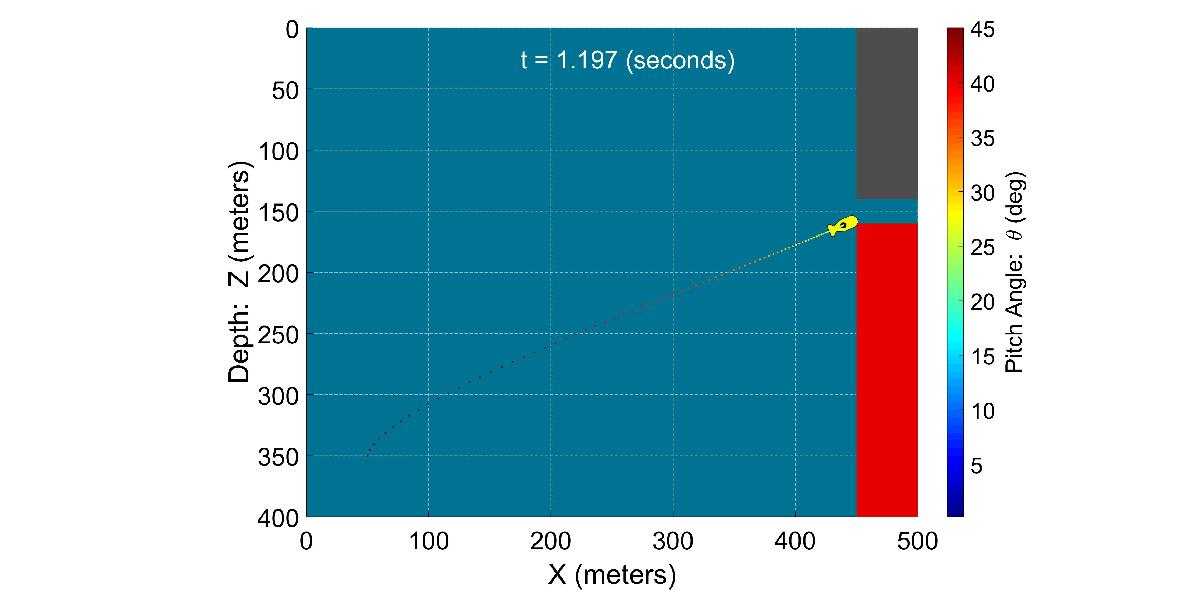

**Iteration 2:**

Now as the control input was still within the given limits some of the poles were placed further on the left hand side to see their effect:

Closed Loop Poles Selected: p = [-2.5,-7.5,-5.5,-6.5,-7,-3.5]

In this case, maximum control input was well above the given constraint (u_max = 6.5522e+06). Also the submarine did not pass through the tunnel.

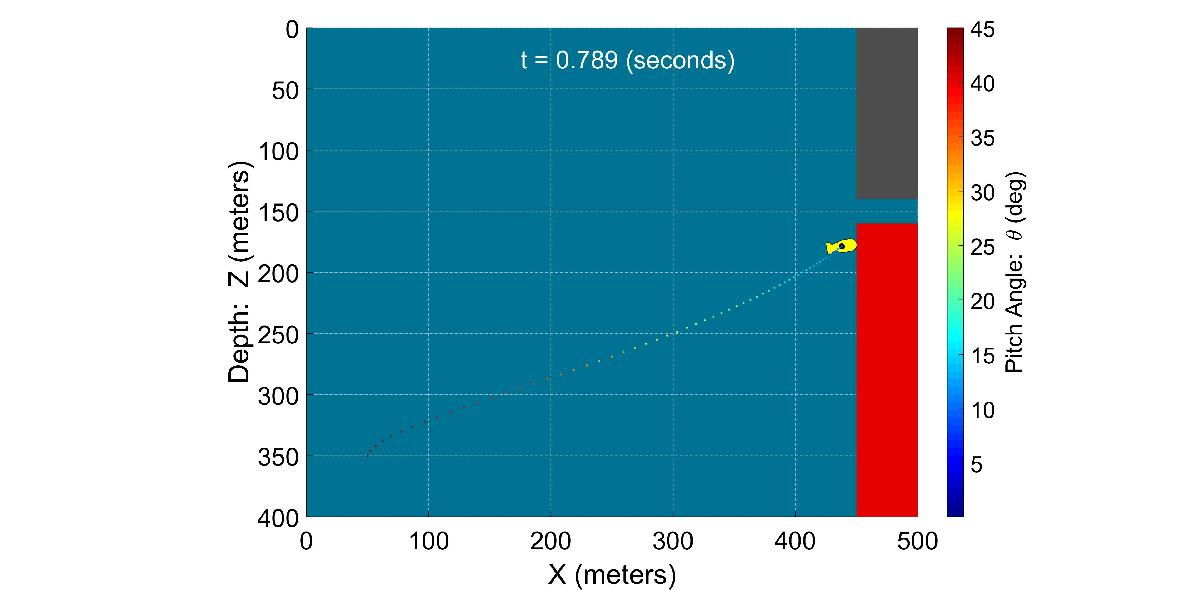

**Iteration 3:**

Now as a tentative limit was determined for the poles along the real axis, the following set of poles were selected:

Closed Loop Poles Selected: p = [-3,-3,-6,-6,-6.5,-2]

In this case, the submarine passes through the tunnel in a time of 3.346 sec which is within the limits of (2-5sec). Also the control input is within the limit of 3e6 (u_max = 2.14100e+06). This was a successfull iteration in terms of falling within the given constraints.

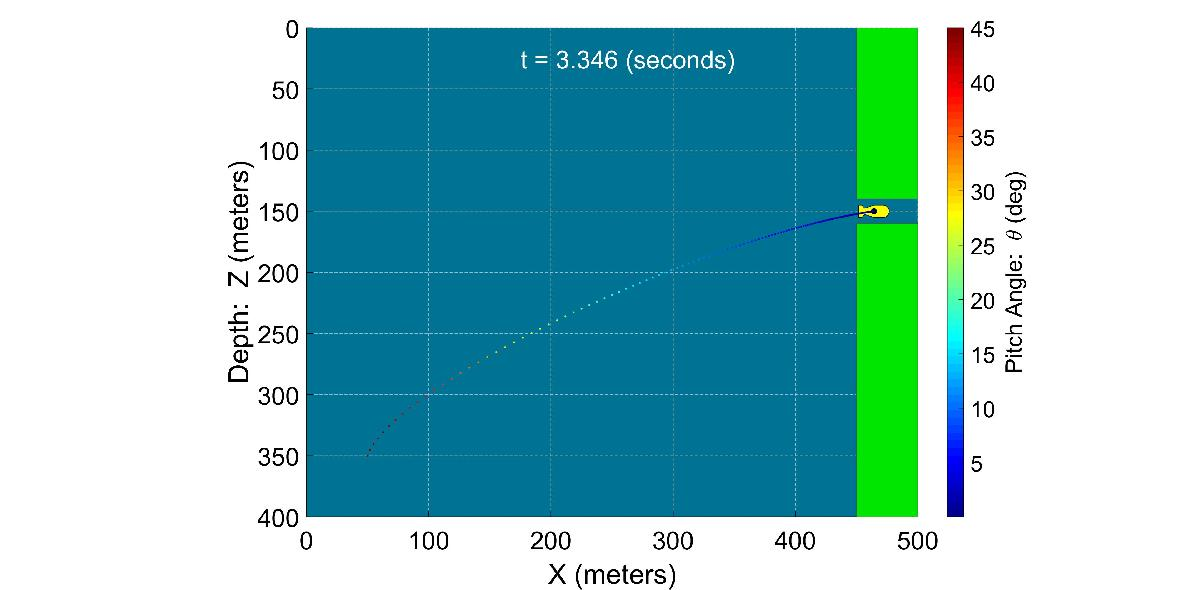

**Iteration 4:**

Now complex poles were selected to see their effect on the system.

Closed Loop Poles Selected: p= [-3+0.5i,-3-0.5i,-6,-7,-2+1i,-2-1i]

In this case, the submarine did not pass through the tunnel even though the maximum control effort was within limits (u_max = 2.3743e+06). Also, it was observed that the the submarine starts rotating about its vertical axis. This can be avoided by reducing the damping. The submarine reached the tunnel within 1.197 sec which is indicates that we still have some scope  to reduce $\omega_n$i.e the radius within which the poles are selected in the complex plane.

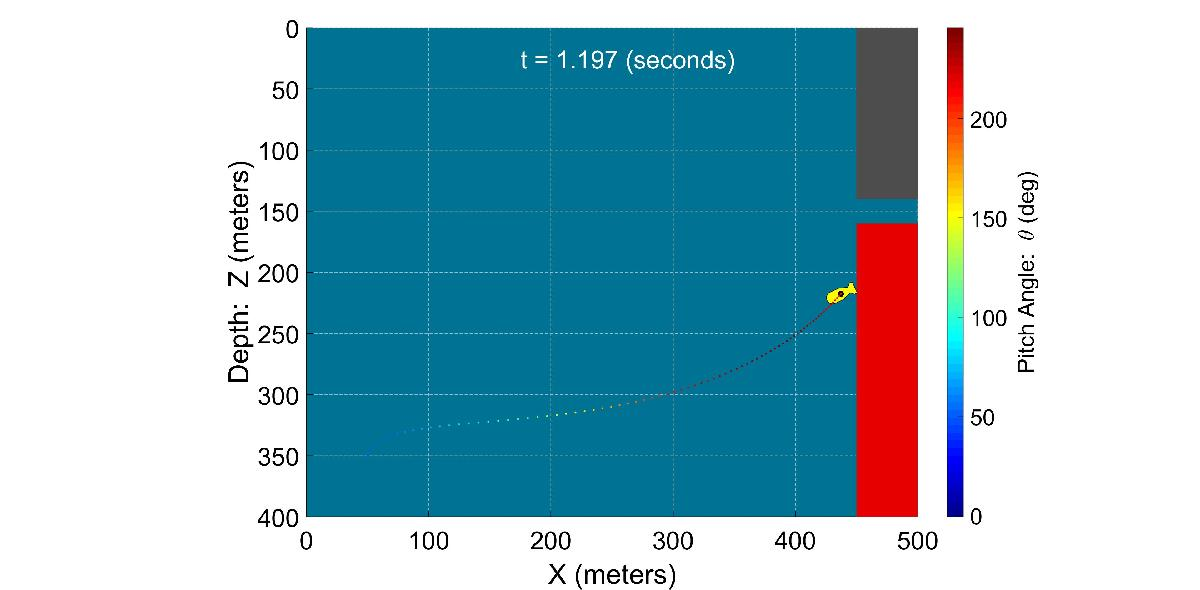

**Iteration 5:**

This is the final iteration which was selected whose poles were decided based on the conclusions from the previous iterations.

Closed Loop Poles Selected: p = [-3,-3,-6,-7,-6.5,-2]

In this iteration, the time required for the submarine to enter the tunnel was 2.868 sec which is within the given limits. The control effort is 2.4e6 which is also within the maximum limit of 3e6.

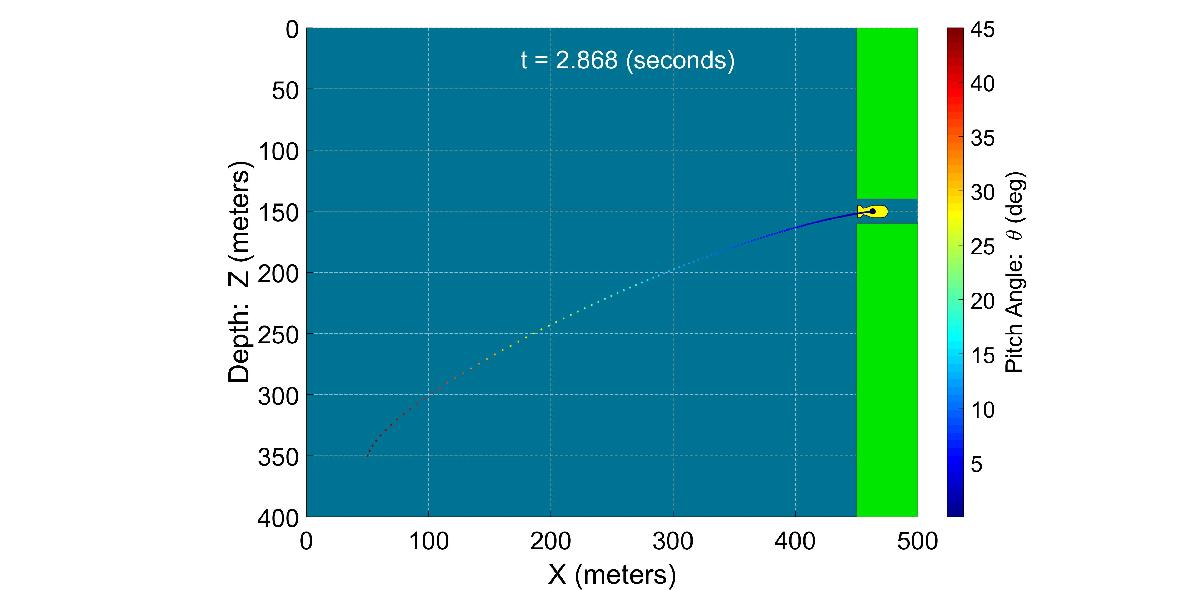

The iterations are summarized in the table below. It should be noted that in the tables the 'New_Settling_Times_T' represents the settling time (in sec) for the three outputs - ($\left.\theta ,Z,X\right)$- respectiveley in this order.

Iteration = {'Iteration 1';'Iteration 2';'Iteration 3';'Iteration 4';'Iteration 5'};
Desired_Closed_Loop_Poles = [-1 -2 -3 -5 -3 -4;-2.5 -7.5 -5.5 -6.5 -7 -3.5;-3 -3 -6 -6 -6.5 -2;...
    -3+0.5i -3-0.5i -6 -7 -2+1i -2-1i;-3 -3 -6 -7 -6.5 -2];
Enters_tunnel = {'No';'No';'Yes';'No';'Yes'};
Maximum_control_signal = [2.8081e+06;6.5522e+06;2.14100e+06;2.3743e+06;2.4e6];
New_Settling_Times_T = [3.5988 1.2467 1.2728;1.3476 1.1170 0.8516;1.2249 1.2412 1.6706;2.6846 2.1135 1.2816; 1.2230 1.1954 1.6224];


T_1 = table(Iteration, Desired_Closed_Loop_Poles, Enters_tunnel,Maximum_control_signal, New_Settling_Times_T);
T_1.Desired_Closed_Loop_Poles = categorical(T_1.Desired_Closed_Loop_Poles);

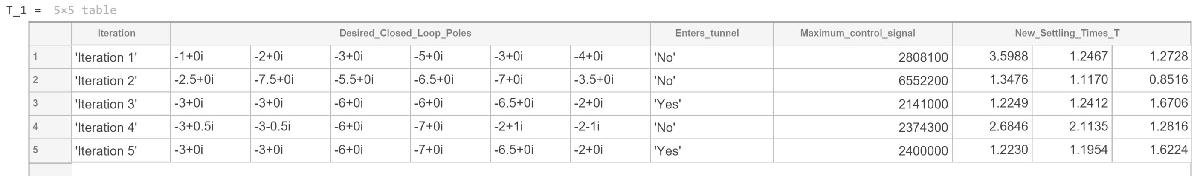

**Final Design Plots:**

The final design plots shows the two position outputs, pitch angle and the three control input signals respectively. These plots correspond to iteration 5 which was selected as the final iteration. It should be noted that the Closed LoopResponse for surge and heave have been plotted in the new coordinate frame.

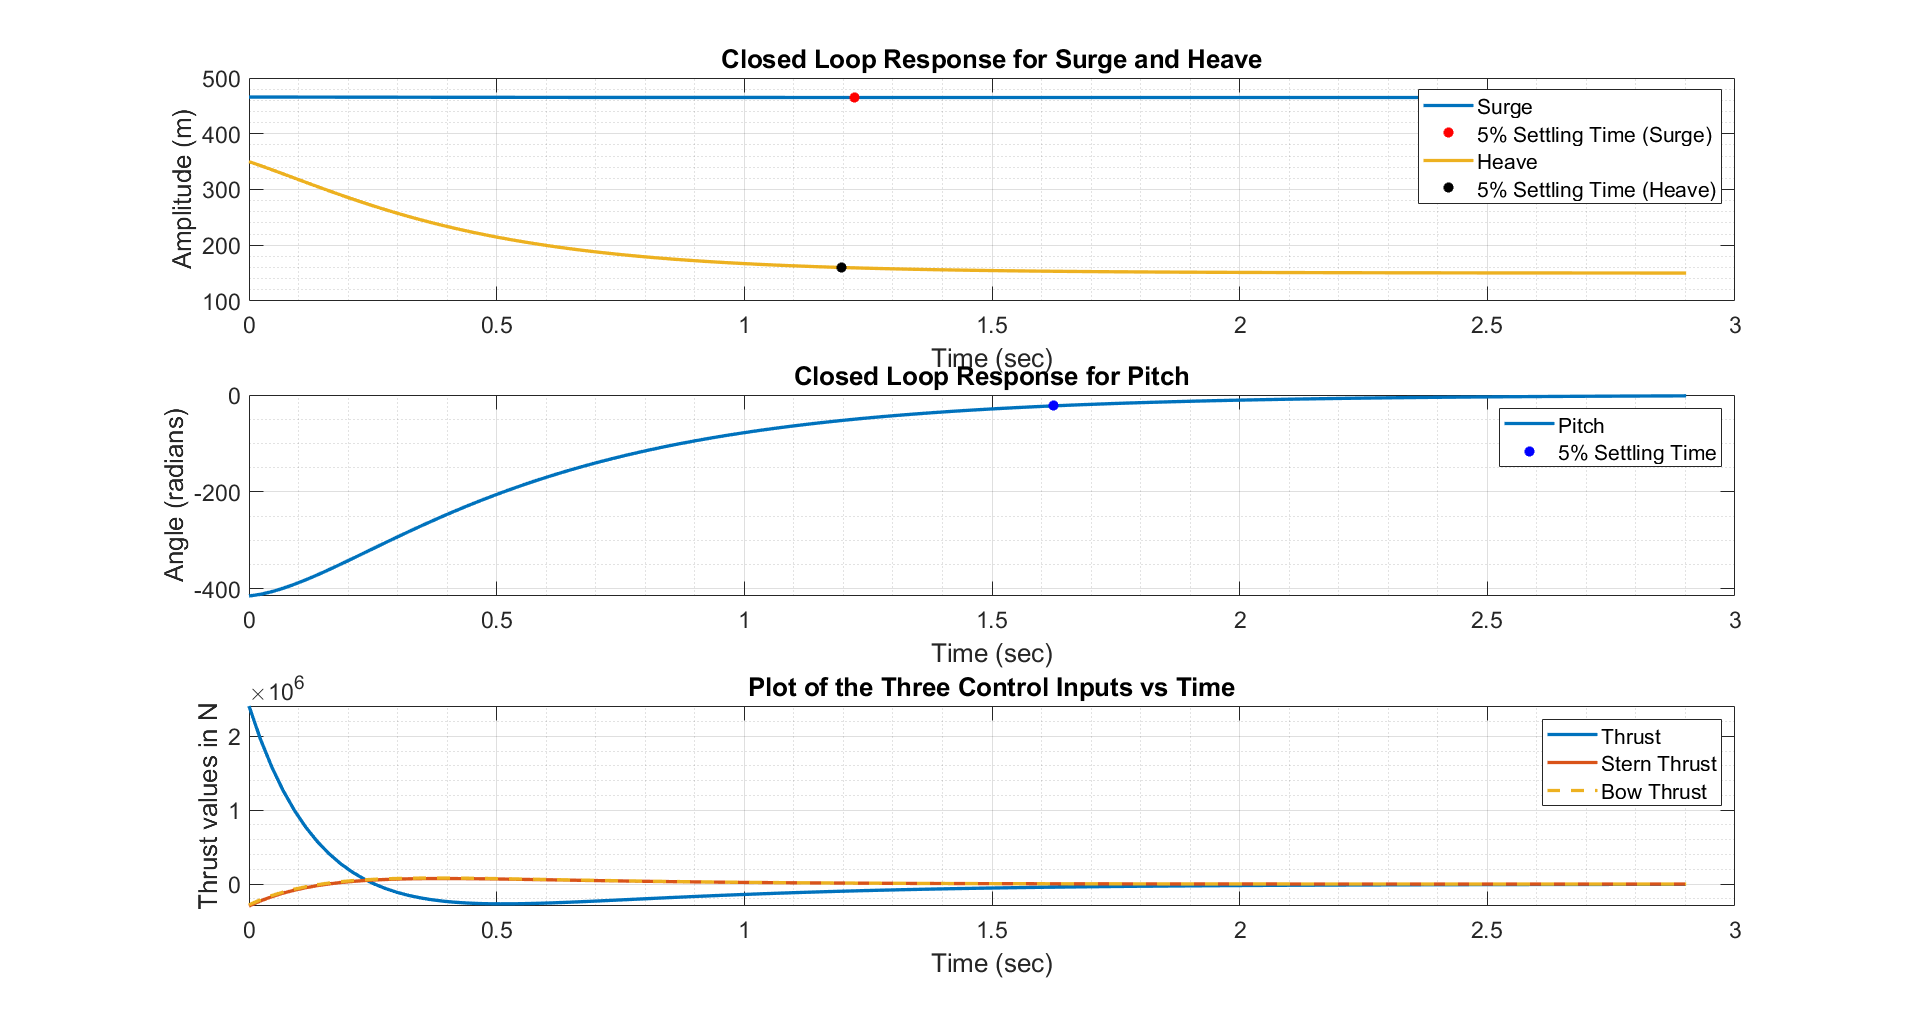

figure (2)
subplot(3,1,1);
vq1_new = interp1(t_2,y_2_new(:,3),New_Settling_Times(1,3));
plot(t_2,y_2_new(:,3),New_Settling_Times(1,3),vq1_new,'r*','LineWidth',2);
hold on
vq2_new = interp1(t_2,y_2_new(:,2),New_Settling_Times(1,2));
plot(t_2,y_2_new(:,2),New_Settling_Times(1,2),vq2_new,'k*','LineWidth',2);
title('Closed Loop Response for Surge and Heave');
xlabel('Time (sec)')
ylabel('Amplitude (m)')
hold off
legend('Surge', '5% Settling Time (Surge)','Heave','5% Settling Time (Heave)')
grid on
set(gcf,'Units','Normalized','OuterPosition',[0,0.04,1,0.96]);
set(gca,'FontSize',14)
grid minor

subplot(3,1,2);
vq3_new = interp1(t_2,y_2_new(:,1),New_Settling_Times(1,1));
plot(t_2,y_2_new(:,1),New_Settling_Times(1,1),vq3_new,'b*','LineWidth',2);
xlabel('Time (sec)')
ylabel('Angle (radians)')
legend('Pitch','5% Settling Time')
title('Closed Loop Response for Pitch')
grid on
set(gcf,'Units','Normalized','OuterPosition',[0,0.04,1,0.96]);
set(gca,'FontSize',14)
grid minor

subplot(3,1,3);
plot(t_2,u_t(1,:),'LineWidth',2)
hold on
plot(t_2,u_t(2,:),'LineWidth',2)
hold on
plot(t_2,u_t(3,:),'--','LineWidth',2)
legend('Thrust','Stern Thrust','Bow Thrust')
xlabel('Time (sec)')
ylabel('Thrust values in N')
title('Plot of the Three Control Inputs vs Time')
hold off
grid on
grid minor
set(gcf,'Units','Normalized','OuterPosition',[0,0.04,1,0.96]);
set(gca,'FontSize',14);

**Important Observations:**

- From the plot of 'control input signals vs time', it can be seen that the the Thrust ($\left.X_T \right)$contributes the most i.e. it has a very high value as compared to the other two signals. As we were not able to specifically tune for a particular control input, this can be achieved by using optimal control techniques such as LQR.

- The placement of complex poles was difficult to achieve as compared to that of the real poles since there were two parameters: natural frequency ($\left.\omega_n \right)\;$and the damping ratio ($\left.\zeta \right)$to be adjsuted for each pole.

- The closed loop response for Pitch settles down to zero whereas those for surge and heave settle at different values. This is corroborated by the fact that while changing the coordinate frame, only the 'X' and 'Z' frames were translated. It can also be visually seen from the animate function as the submarine becomes horizontal at the end shown by the blue legend (colorbar)).